%% DSP Week 10 — Bilinear Transform (IIR LP)  — Live Script Ready
% This script mirrors your Obsidian note:
% 1-A .. 1-F with plots saved to:
%   C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images
%
% Tip: Run sections one-by-one. After each section, jot the key value into your note.


## Setup & Paths


clear; close all; clc;
Ts   = 1e-3;                 % Sampling period [s]
Fs   = 1/Ts;                 % Sampling frequency [Hz]
fp_hz= 147.58;               % Digital passband edge [Hz] (given)
alpha= 2/Ts;                 % BLT alpha

% Image export dir (Windows path). Use fullfile for safety.
imgdir = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images';
if ~exist(imgdir,'dir'); mkdir(imgdir); end

% A small helper for safe exports
export = @(fname) exportgraphics(gcf, fullfile(imgdir,fname), 'Resolution', 300);


## 1-A) Digital passband angular freq (rad/sample)

wp = 2*pi*(fp_hz/Fs);  % rad/sample
fprintf('[1-A] omega_p = %.6f rad/sample\n', wp);

[1-A] omega_p = 0.927272 rad/sample


## 1-B) Prewarp to analog domain (Omega_p, Fp)

Op = alpha * tan(wp/2);   % rad/s
Fp = Op/(2*pi);           % Hz
fprintf('[1-B] Omega_p = %.6f rad/s, Fp = %.6f Hz\n', Op, Fp);

[1-B] Omega_p = 999.971587 rad/s, Fp = 159.150421 Hz


## 1-C) Analog Butterworth (order 1), cutoff at Omega_p  — full checks

Oc   = Op;                % cutoff = prewarped passband
Ban  = [Oc];              % numerator
Aan  = [1 Oc];            % denominator

% --- Analytical note (prototype -> scaled) ---
% Prototype: H_p(s) = 1/(s+1)
% Lowpass->Lowpass scaling with cutoff Oc: H_a(s) = H_p(s/Oc) = Oc/(s+Oc)
% -> This matches Ban/Aan above.

% --- Verify with lp2lp() ---
[Bproto, Aproto] = deal(1, [1 1]);
[B_lp2lp, A_lp2lp] = lp2lp(Bproto, Aproto, Oc);   % should be Oc / (s + Oc)
fprintf('[1-C] Analytical  : B=[%.6f], A=[1 %.6f]\n', Ban(1), Aan(2));

[1-C] Analytical  : B=[999.971587], A=[1 999.971587]


fprintf('[1-C] lp2lp()     : B=[%.6f], A=[1 %.6f]\n', B_lp2lp(1), A_lp2lp(2));

[1-C] lp2lp()     : B=[999.971587], A=[1 999.971587]


assert( abs(B_lp2lp(1)-Ban(1))<1e-10 && abs(A_lp2lp(2)-Aan(2))<1e-10, ...
        'lp2lp verification failed');

% Magnitude check exactly at Fp (use analytic eval instead of freqs)
wFp  = 2*pi*Fp;
H_Fp = polyval(Ban, 1j*wFp) / polyval(Aan, 1j*wFp);
fprintf('[1-C] |H(j*w_p)| = %.6f  (%.4f dB) at Fp=%.6f Hz\n', ...
        abs(H_Fp), 20*log10(abs(H_Fp)), Fp);

[1-C] |H(j*w_p)| = 0.707107  (-3.0103 dB) at Fp=159.150421 Hz


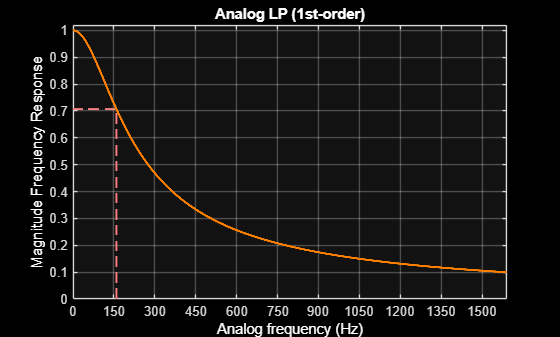



% --- Analog magnitude (LINEAR), dark theme + blue dashed guide box ---
f  = linspace(0, 10*Fp, 5000);                 % show a long tail (≈ up to 1600 Hz)
H  = freqs(Ban, Aan, 2*pi*f);
mag = abs(H);

% exact magnitude at Fp (should be 1/sqrt(2))
H_Fp_exact = polyval(Ban, 1j*2*pi*Fp) / polyval(Aan, 1j*2*pi*Fp);
mag_fp     = abs(H_Fp_exact);

fig = figure('Name','Analog LP magnitude (linear)','Color','k');
ax  = axes('Parent',fig);
ax.Color = 'k';
ax.XColor = [1 0 0];
ax.YColor = [1 0 0];
ax.GridColor = [0.4 0.4 0.4];
ax.LineWidth = 1.0;

plot(f, mag, 'Color', [1 0.5 0], 'LineWidth', 1.8); hold on; grid on;

% dashed guide box at (Fp, |H|=1/sqrt(2))

plot([0, Fp],   [mag_fp, mag_fp], 'Color', [1 0.5 0.5], 'LineWidth', 1.4, 'LineStyle','--');
plot([Fp, Fp],  [0, mag_fp],      'Color', [1 0.5 0.5], 'LineWidth', 1.4, 'LineStyle','--');

xlabel('Analog frequency (Hz)', 'Color', 'w');
ylabel('Magnitude Frequency Response', 'Color', 'w');
title('Analog LP (1st-order)', 'Color', 'w');

xlim([0, 10*Fp]);          % e.g., 0 .. ~1590 Hz like the solution
ylim([0, 1.02]);           % linear magnitude 0..1

% finer ticks every 100 Hz
xticks(0:150:round(10*Fp, -2));
export('Week10_AnalogLP_mag.png');

## 1-D) Bilinear transform to digital H(z)


[Bz, Az] = bilinear(Ban, Aan, Fs);
b0 = Bz(1); b1 = Bz(2); a1 = Az(2);

fprintf('[1-D] Digital H(z):  B=[%.6f %.6f],  A=[1 %.6f]\n\n', b0, b1, a1);

[1-D] Digital H(z):  B=[0.333327 0.333327],  A=[1 -0.333346]




% Print clean ASCII fraction form
fprintf('H_d(z) =\n');

H_d(z) =


fprintf('          %.6f + %.6f·z^(-1)\n', b0, b1);

          0.333327 + 0.333327·z^(-1)


fprintf('  -----------------------------------\n');

  -----------------------------------


fprintf('          1 %.6f·z^(-1)\n\n', a1);

          1 -0.333346·z^(-1)




% Quick sanity checks
Hdc  = (b0+b1)/(1+a1);
pole = -a1;
fprintf('H(1) = %.6f (expect ~1)\n', Hdc);

H(1) = 1.000000 (expect ~1)


fprintf('pole = %.6f (|pole|<1 stable)\n', pole);

pole = 0.333346 (|pole|<1 stable)


## 1-E) Verify digital passband with freqz


n = 1024;                                 % dense grid for accurate readout
[Hdz, fHz] = freqz(Bz, Az, n, Fs);        % Bz,Az from 1-D

% Value at f_p (closest bin)
[~,k] = min(abs(fHz - fp_hz));
H_at_fp = Hdz(k);
dB_at_fp = 20*log10(abs(H_at_fp));
fprintf('[1-E] |H_d(e^{jω_p})| = %.6f  (%.4f dB) at f_p=%.5f Hz\n', ...
        abs(H_at_fp), dB_at_fp, fHz(k));

[1-E] |H_d(e^{jω_p})| = 0.707437  (-3.0062 dB) at f_p=147.46094 Hz



% Optional: nearest -3 dB frequency
dB = 20*log10(abs(Hdz));
[~,k3] = min(abs(dB + 3));
f3dB = fHz(k3);
fprintf('[1-E] Nearest -3 dB at f ≈ %.6f Hz (should be close to f_p)\n', f3dB);

[1-E] Nearest -3 dB at f ≈ 147.460938 Hz (should be close to f_p)



% Exact evaluation at f_p (no grid error)
wp_exact = 2*pi*fp_hz/Fs;         % rad/sample
z = exp(1j*wp_exact);
H_exact = (b0 + b1*z.^-1) / (1 + a1*z.^-1);
fprintf('[1-E exact] |H| = %.6f  (%.4f dB) at f_p=%.5f Hz\n', ...
        abs(H_exact), 20*log10(abs(H_exact)), fp_hz);

[1-E exact] |H| = 0.707107  (-3.0103 dB) at f_p=147.58000 Hz


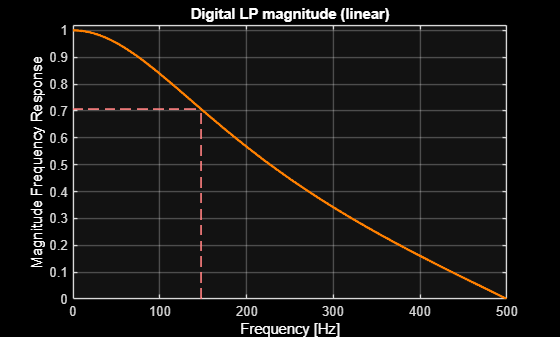



% ---- Plot (dark theme, ORANGE curve, RED axes, WHITE text) — LINEAR magnitude ----
mag = abs(Hdz);                       % linear magnitude (0..1)
mag_fp = abs(H_exact);                % exact |H| at f_p for the guide box

fig = figure('Name','Digital LP magnitude (linear)','Color','k');
ax  = axes('Parent',fig);
ax.Color = 'k';  
ax.XColor = [1 0 0];  
ax.YColor = [1 0 0];
ax.GridColor = [0.4 0.4 0.4];  
ax.LineWidth = 1.0;

% main curve (linear magnitude)
plot(fHz, mag, 'Color', [1 0.5 0], 'LineWidth', 1.8); hold on; grid on;

% guide "box" at (f_p, |H|): horizontal then vertical, soft red
plot([0, fp_hz], [mag_fp, mag_fp], 'Color', [1 0.5 0.5], 'LineWidth', 1.2, 'LineStyle','--');
plot([fp_hz, fp_hz], [0, mag_fp],   'Color', [1 0.5 0.5], 'LineWidth', 1.2, 'LineStyle', '--');

xlabel('Frequency [Hz]', 'Color', 'w');
ylabel('Magnitude Frequency Response', 'Color', 'w');   % linear scale label
title('Digital LP magnitude (linear)', 'Color', 'w');

xlim([0 Fs/2]);                      % 0..500 Hz like the solution
ylim([0 1.02]);                      % linear magnitude range

export('Week10_DigitalLP_mag.png');

## 1-F) Difference equation (print nicely)

fprintf('[1-F] Difference equation coefficients:\n');

[1-F] Difference equation coefficients:


fprintf('      b0 = %.10f\n', b0);

      b0 = 0.3333270193


fprintf('      b1 = %.10f\n', b1);

      b1 = 0.3333270193


fprintf('      a1 = %.10f\n', a1);

      a1 = -0.3333459614



% Pretty ASCII equation
fprintf('\ny[n] = %.6f*x[n] + %.6f*x[n-1] + (%.6f)*y[n-1]\n\n', b0, b1, -a1);


y[n] = 0.333327*x[n] + 0.333327*x[n-1] + (0.333346)*y[n-1]




% (Optional) impulse response quick check
L = 32; x = [1; zeros(L-1,1)];
y_imp = filter([b0 b1], [1 a1], x);
fprintf('[1-F] First five h[n]: '); fprintf('%.6f ', y_imp(1:5)); fprintf('\n');

[1-F] First five h[n]: 0.333327 0.444440 0.148152 0.049386 0.016463 


## Extras) DC/NYQ gains & Unit-step response

z1 = 1; zneg1 = -1;
H_dc  = polyval(Bz, z1)   / polyval(Az, z1);
H_nyq = polyval(Bz, zneg1)/ polyval(Az, zneg1);
fprintf('[Extras] H(1)=%.6f,  H(-1)=%.6f\n', H_dc, H_nyq);

[Extras] H(1)=1.000000,  H(-1)=0.000000


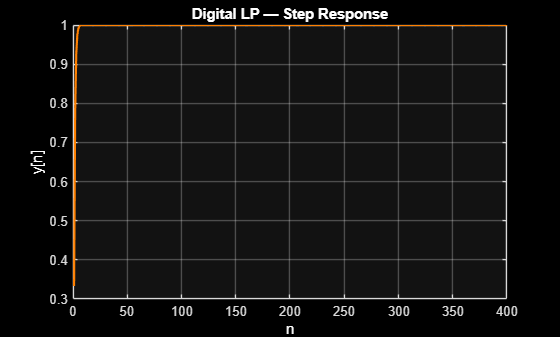


L = 400; u = ones(L,1);
y = filter(Bz, Az, u);

% --- Digital LP step response (dark theme: orange line, red axes, white text) ---
fig = figure('Name','Digital step response','Color','k');
ax  = axes('Parent',fig);
ax.Color = 'k';
ax.XColor = [1 0 0];
ax.YColor = [1 0 0];
ax.GridColor = [0.4 0.4 0.4];
ax.LineWidth = 1.0;

plot(y, 'Color', [1 0.5 0], 'LineWidth', 1.6); % orange line
grid on;

xlabel('n', 'Color', 'w');
ylabel('y[n]', 'Color', 'w');
title('Digital LP — Step Response', 'Color', 'w');

export('Week10_DigitalLP_step.png');